## Basin of attraction for the V != 0 stable spirals

### LHS for initial values of H, I, V

init_bound = [0, 0, 0; 300, 100, 5e5];
N = 1000;
lhs_rad = lhsdesign(N, 3);
init_lhs = lhs_rad .* init_bound(1, :) + lhs_rad .* (init_bound(2, :) - init_bound(1, :));

% load parameters
par_base = importdata('xppaut\par_cmccl2_bifurcation.txt');
par_base = par_base.data;
par_consider = par_base;
par_consider_idx = (1:57);

m = size(init_lhs, 1);
n = 14;

% load base initial values
y0_base = importdata('init_base.txt');
y0_base = y0_base.data;
y0s = zeros(m, n);
for i = 1:m
    y0s(i, :) = y0_base;
    y0s(i, 1:3) = init_lhs(i, :);
end

### Solve ODEs for each initial value and find the final state

tspan = 0:1:50000;
y_ss = zeros(m, n);
TF_arr = false(m, 1);

p = parpool(20);

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 20).


parfor i = 1:m
    y_i = solve_odes(par_base, par_consider_idx, par_consider, y0s(i, :), tspan);
    if size(y_i) == [length(tspan) n]
        y_ss(i, :) = y_i(end, :);
    else
        TF_arr(i) = true;
    end
end

> In ode15s (line 723)
In solve_odes (line 11)
In 

% y_ss(TF_arr, :) = [];
% [m, ~] = size(y_ss);
delete(p);

% write y_ss to a file
file_id = fopen('xppaut\y_ss_basin.txt', 'w');
for i = 1:m
    fprintf(file_id, '%d ', i);
    fprintf(file_id, '%f ', y_ss(i, :));
    fprintf(file_id, '\n');
end

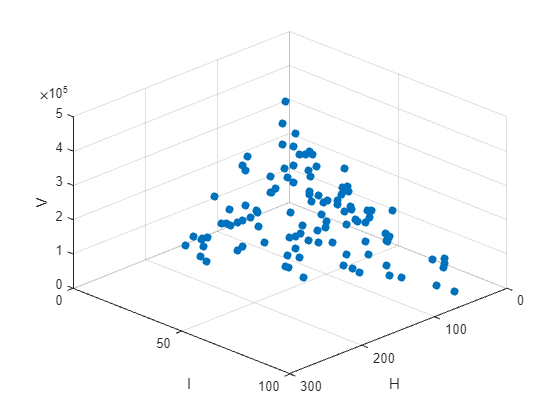

y_ss = importdata('xppaut\y_ss_basin.txt');
TF_basin = false(m, 1);
for i = 1:m
    if y_ss(i, 4) > 30000
        TF_basin(i) = true;
    end
end
init_basin_idx = y_ss(TF_basin, 1);
init_basin = init_lhs(init_basin_idx, :);

figure;
scatter3(init_basin(:, 1), init_basin(:, 2), init_basin(:, 3), 'filled'); hold on;
set(gca, 'XLim', [0 300], 'YLim', [0 100], 'ZLim', [0 5e5]);
xlabel('H'); ylabel('I'); zlabel('V');
view([1, 1, 1]);


% k = boundary(init_basin);
% trisurf(k, init_basin(:, 1), init_basin(:, 2), init_basin(:, 3), 'Facecolor', 'blue');